Exercise 4.3

clear all
Newton = 0; % 0: Use Steepest Descent ; 1: Use Newton method
c1 = 0.1;
rho = 0.5;
MaxIter = 30;
f = @( x ) ((1 - x(1) ) .^2 + ( x(2) - x(1) ^2) ^2) ;
df = @( x ) ([ -2*(1 - x(1) ) - 4* x(1) *( x(2) - x(1) ^2) ; 2*( x(2) - x(1)^2) ]) ;
H = @( x ) ([2 -4* x(2) +12* x(1) .^2 , -4* x(1) ;-4* x(1) ,2]) ;
x = [ -1; -1]; % initial x
f_eval (1) = f ( x ) ;
for k = 1: MaxIter
    alpha = 1; % step length
    if Newton
        sk = -H ( x (: , k ) ) \ df ( x (: , k ) ) ; % Newton direction
    else
        sk = - df ( x (: , k ) );  % Steepest descent
    end
    while f ( x (: , k ) + alpha * sk ) >f ( x (: , k ) ) + c1 * alpha * df ( x (: , k ) )'* sk % Armijo condition
        alpha = rho * alpha ; % backtrack step length if Armijo condition not satisfied
    end
    x (: , k +1) = x (: , k ) + alpha * sk ;
    f_eval ( k +1) = f ( x (: , k +1) ) ;
end
x

x =    -1.0000    0.5000    0.2500    0.6719    0.6034    0.8544    0.7531    0.8811    0.8187    0.8678    0.8400    0.8772    0.8792    0.9079    0.9022    0.9313    0.9232    0.9388    0.9344    0.9546    0.9467    0.9596    0.9556    0.9643    0.9624    0.9749    0.9678    0.9773    0.9723    0.9797    0.9760
   -1.0000   -0.5000    0.2500    0.1562    0.4514    0.4077    0.4883    0.5672    0.6195    0.6449    0.6990    0.7006    0.7695    0.7704    0.8242    0.8217    0.8445    0.8464    0.8813    0.8793    0.8953    0.8956    0.9082    0.9094    0.9197    0.9229    0.9298    0.9332    0.9387    0.9420    0.9465


Exercise 6

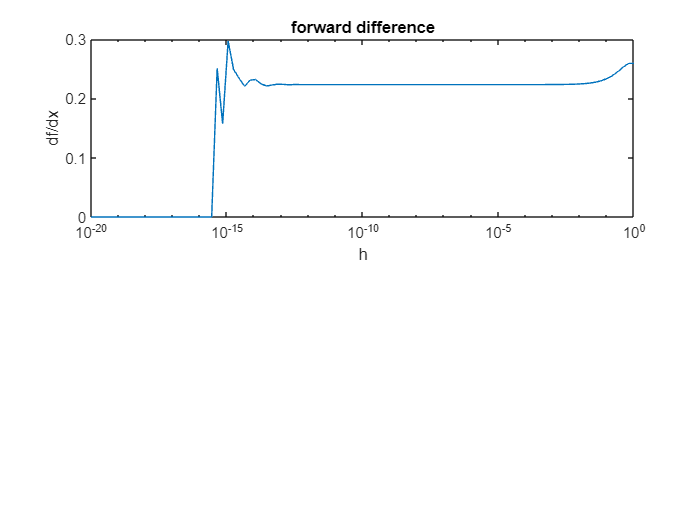

clear
% ESQ4exer6.m
% Visualization of the errors in finite differencing
% objfnc.m contains objective function for which finite difference
% gradient is calculated
clf, hold off, clear
% Point at which finite difference gradient is calculated
x0 = 1.5;
% Vector of finite difference steps
hvec = logspace(-20,0,100);
% Calculation of finite difference gradient for range of h values

%function
objfnc = @(x) 1 - 2*x*exp(-x);
for i=1:1:length(hvec)
    h = hvec(i);
    fx0 = objfnc(x0);
    fx0plush = objfnc(x0+h);
    dfdx(i) = (fx0plush - fx0)/h;
end
% Plotting finite difference gradients
subplot(211)
semilogx(hvec,dfdx)
xlabel('h'), ylabel('df/dx'), title('forward difference')

%subplot(212)
%semilogx(hvec,dfdxcentral)
%xlabel(’h’), ylabel(’df/dx’), title(’central difference’)
subplot
